ABRMagnitude=Figure2Data(:,3)-Figure2Data(:,2);
StdDev=std(AverageBaselineResponseNoiseMagnitude);
TwoThresholdCriteria=StdDev*2;
FigureTwoB=plot(Figure2Data(:,1), ABRMagnitude,'-o');
set(FigureTwoB,'markerfacecolor',get(FigureTwoB,'color'))
xlim([0 90]);
hold on
TwoThres=yline(TwoThresholdCriteria,'-.b');
BaseLinePlot=plot(Figure2Data(:,1), Figure2Data(:,4),'o','color','blue')

BaseLinePlot =   Line with properties:

              Color: [0 0 1]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [20 25 30 40 60 80]
              YData: [0.5000 0.6000 0.4500 0.8000 0.6500 0.6500]
              ZData: [1×0 double]

  Show all properties


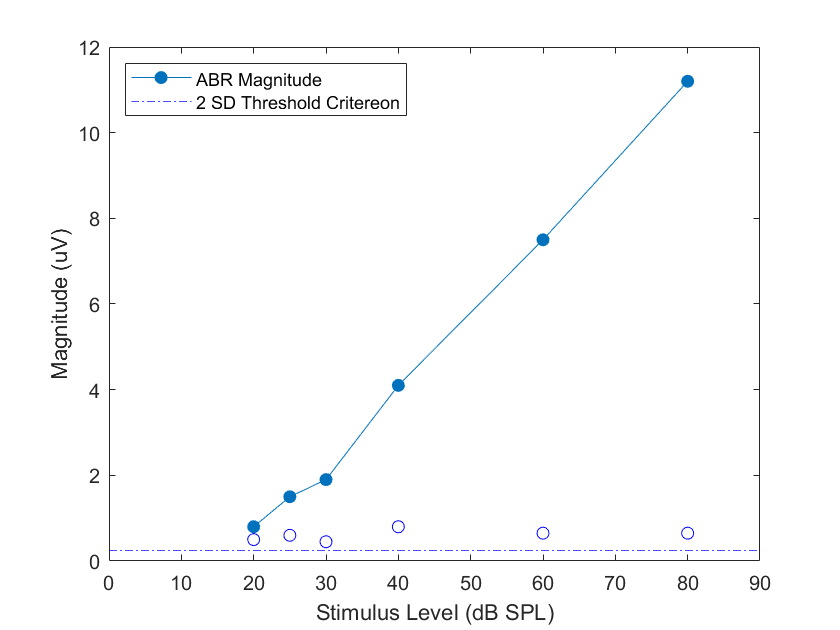

hold off
xlabel("Stimulus Level (dB SPL)");
ylabel("Magnitude (uV)");
legend({'ABR Magnitude','2 SD Threshold Critereon'},'Location','northwest');